# Ultrasound Technologies for Medical Applications Assigment

### ***Author : Matteo Guglielmi, 232088***

## ***Assigment objectives***

The objectives of this assigment are :

- expertimenting how to set up the transmission parameters of a professional US scanner, in this specific case ULA-OP, and see the effects of different parameters on the final product (image)

- estimate the speed of sound and the attenuation coefficient of the gelatine in function of depth and frequency.

In the following, you can find my proposed solution to fulfill the requests. 

Just to note, I decided to use and interactive script in order to let any reviewer to better understand the workflow. Each section can be run separately through the shortcut `Ctrl+Enter.`

% CLI commands
clear
close all
clc

% Adding useful folders to the path
addpath("Read ULA-OP");
addpath("Read ULA-OP/Class");
addpath("Read ULA-OP/ULAOP");
addpath("Data/SOS Data");

## Constants declarations

In the development of the problem, we obviously need to take into account some characteristics of the scanner we're using to acquire the data. Since these are intrinsic characteristics, the latter are considered as constants in the code. 

The features of main interest are:

- the sampling frequency at which the scanner compose a pixel (in case of ULA-OP it is set to 50 MHz)

- the pitch between two sensors which is 0.245 mm (feature of the LA533 probe)

Other important aspects to be considered while performing the measures were:

- the bandwidth of the linear probe LA533

- transmission parameters to enhance and adjust the appearence of the image, i.e. transmission frequecy, pulse length (indirectly infered from nCycles and transmission frequency), transmission focal depth, sub-aperture dimension both in Tx and Rx, transmission amplitude and analogic time gain compensator a/b to increase amplitudes in function of depth.

% Constants declaration
fs=50e6;            % sampling frequency [Hz]           
Nlines=129;         % number of lines in a frame
OffSet=0.005;       % transmit offset [m]
Pitch=0.245;        % pitch [mm]

## Data reading

The first task to adderss is to define the SOS in the investigated mean. In order to do so, I've selected 4 rfb data where the second wire was visible in order to avoid possible problems when detecting the maximum and also to set up a limit in the number of images to consider. 

In the following lines of code, an average will be taken across the speed of sound estimation to have a less-noisy predictition.

% Reading file
DataObj=DataUlaopPostBeamforming('Group1F6MHzNC15aTX64aRX32foc1000Amp1Tgc00TestGain10Vista2filo_SliceRf.rfb'); 
Read(DataObj,'firstPri',1,'npri',GetTotalPri(DataObj));                     % Read all the avaialble PRIs
[nGate,nPri]=size(DataObj.LastReadData);                                    % Extract the number of gate and the number of pris
time=DataObj.LastReadTime(1)+(0:nGate-1)/DataObj.fs;                        % Time axis
rf=DataObj.LastReadData;

### Visualizing the read data

To better visualize and understand what's inside the image, I decided to plot and analyse the module of the hilbert transfrom which allows to extract the envelop. The latter allow us to have a smoother image which simplifies the analysis.

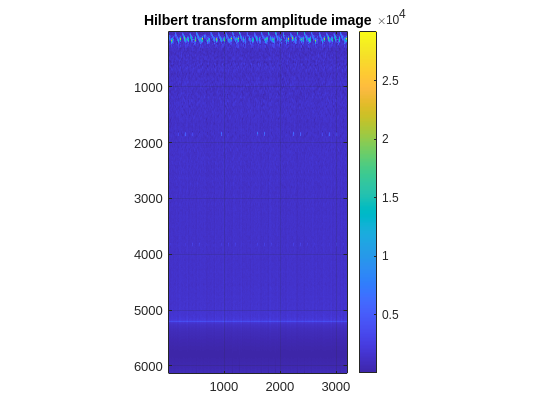

% Plotting extracted image
figure;
imagesc(abs(hilbert(rf)));
title("Hilbert transform amplitude image");
colorbar;
grid on;
axis image;

From a visual analysis, the first frame is considered to start at line 100. Since the lateral dimension of a frame is known, then we can extract an image from the time series.

% Select one frame
framestart=100;
c0=1540;                                                                    % propagating S.O.S. in empty space. This is used just
                                                                            % visualize the image before computing real S.O.S. Assumed
                                                                            % to be similar to "Soft tissue".
rfIMAGE=rf(:,framestart:framestart+Nlines);                                 % visually select where first frame begins and isolate it
rfIMAGE=rfIMAGE./max(max(rfIMAGE));                                         % image normalization (cathing the max in the matrix)

LateralDimension=(1:Nlines)*Pitch;                                          % this are the spatial locations where the lines ends
LateralDimension=LateralDimension-(Pitch*floor(Nlines/2));                  % this is just to center whatever image which is plotted
Depth=OffSet+(1:nGate)*c0*1/(2*fs);                                         % path that the USW needs to travel to perform an acquisition
                                                                            % of a line

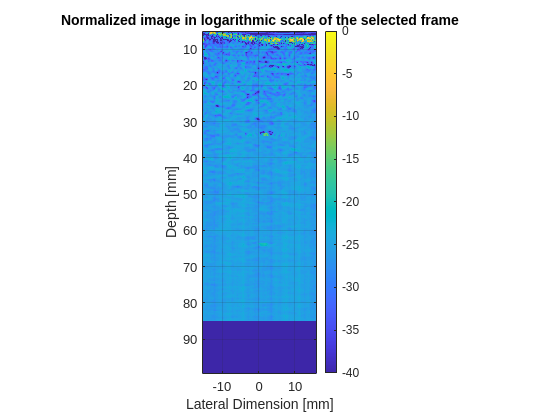

% Plot selected frame
figure;
imagesc(LateralDimension,Depth*1000,20*log10(abs(rfIMAGE)));
clim([-40 0]);                                                              % clips colors to have prettier plots
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Normalized image in logarithmic scale of the selected frame");
colorbar;
grid on;
axis image;    

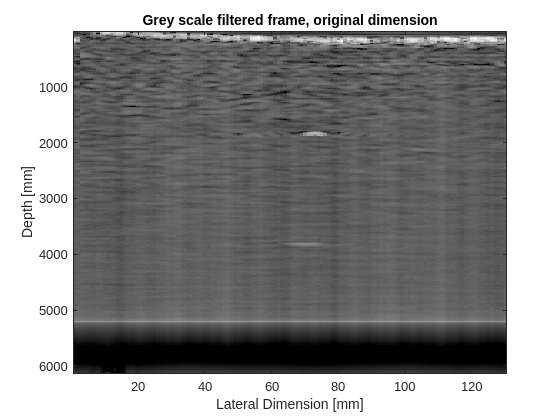

% Plot true dimensions selected frame
figure;
imagesc(20*log10(abs(abs(hilbert(rfIMAGE)))));
clim([-40 0]);
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Grey scale filtered frame, original dimension");
colormap('gray');     

In the last image, it is possible to see how both wires appears in the image and that's the only precaution to be respected to conduct the experiment.

## First S.O.S. approximation

In this section, I'm going to compute a couple of estimations of the S.O.S. within the mean under investigation, specifically:

- as first step, I'm going to define a rough estimation based on just one image (just to test the procedure)

- secondary, I'll be averaging the results across different measurements to smooth out some noise in the computation. Additionally, the variance is computed to have a mesure unit of inconsistency between readings

For simplicity, since the second wire is not always clerly visible, to exploit a wire detection procedure based on a "maximum filtering procedure" I devided the image in half.

% Extract wires
ImageWire1=abs(hilbert(rfIMAGE(1780:1900,65:83)));                          % isolating one of the wires in the frame
                                                                            % pay attention to consider the real dimension of the frame
ImageWire2=abs(hilbert(rfIMAGE(3760:3900,60:83)));   

At this point, a plot to visually address what have been extracted is performed.

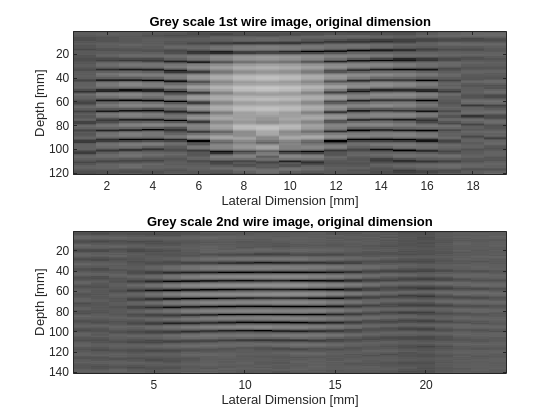

figure;
subplot(2,2,[1 2]);
imagesc(20*log10(abs(ImageWire1)));
clim([-40 0]);
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Grey scale 1st wire image, original dimension");
colormap('gray');     

subplot(2,2, [3 4]);
imagesc(20*log10(abs(ImageWire2)));
clim([-40 0]);
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Grey scale 2nd wire image, original dimension");
colormap('gray');  

As final step for the first point, the positions $(X;Y)$ for both wires are extracted.

[depth1,latdim1]=find(ImageWire1==max(max(ImageWire1)));                     % returns the matrix indices of the maximum point
[depth2,latdim2]=find(ImageWire2==max(max(ImageWire2)));

### S.O.S. calculus

At this point all the ingredients are available to compute the speed of sound as :

- 
$$S.O.S. = \frac{\overline{D_1D_2}}{f_s}$$


dove :

- $D_1$ : depth del primo wire

- $D_2
$ : depth del secondo wire

- $f_s
$ : sampling frequency

offset1wire = 1780;                                                           % starting of first wire image
offset2wire = 3760;                                                           % starting of second wire image
space = 3e-2;                                                                 % known distance between the two wires [mm]                                                             
time1to2 = (abs((offset1wire+depth1)-(offset2wire+depth2))/fs);               % time to travel one-way "space" [s]
SOS = (2*space/time1to2);                                                     % speed of sound taking into consideration that
                                                                              % the wave needs to go back and forth.       
display = ['Approximated S.O.S. : ', num2str(SOS)];                                                                
disp(display)

Approximated S.O.S. : 1511.335


## Speed of sound calculus considering several images

This second phase consists in repeating the procedure applied for the single image scenario to all the other .rfb data.

### Data Reading

% Getting file names
folder = uigetdir();
folderList = dir(fullfile(folder, '*.rfb'));
folderList.name

ans = 'Group1F10MHzNC15aTX64aRX32foc1000Amp1Tgc00TestGain10Vista2filo_SliceRf.rfb'

ans = 'Group1F12MHzNC15aTX64aRX32foc1000Amp1Tgc00TestGain10Vista2filo_SliceRf.rfb'

ans = 'Group1F6MHzNC15aTX64aRX32foc1000Amp1Tgc00TestGain10Vista2filo_SliceRf.rfb'

ans = 'Group1F8MHzNC15aTX64aRX32foc1000Amp1Tgc00TestGain10Vista2filo_SliceRf.rfb'

% Reading files
DataObj2=DataUlaopPostBeamforming(folderList(2).name); 
Read(DataObj2,'firstPri',1,'npri',GetTotalPri(DataObj2));                     % Read all the avaialble PRIs
[nGate2,nPri2]=size(DataObj2.LastReadData);                                   % Extract the number of gate and the number of pris
time2=DataObj2.LastReadTime(1)+(0:nGate2-1)/DataObj2.fs;                      % Time axis
rf2=DataObj2.LastReadData;

DataObj3=DataUlaopPostBeamforming(folderList(3).name); 
Read(DataObj3,'firstPri',1,'npri',GetTotalPri(DataObj3));                     % Read all the avaialble PRIs
[nGate3,nPri3]=size(DataObj3.LastReadData);                                   % Extract the number of gate and the number of pris
time3=DataObj2.LastReadTime(1)+(0:nGate3-1)/DataObj3.fs;                      % Time axis
rf3=DataObj3.LastReadData;

DataObj4=DataUlaopPostBeamforming(folderList(4).name); 
Read(DataObj4,'firstPri',1,'npri',GetTotalPri(DataObj4));                     % Read all the avaialble PRIs
[nGate4,nPri4]=size(DataObj4.LastReadData);                                   % Extract the number of gate and the number of pris
time4=DataObj4.LastReadTime(1)+(0:nGate4-1)/DataObj4.fs;                      % Time axis
rf4=DataObj4.LastReadData;

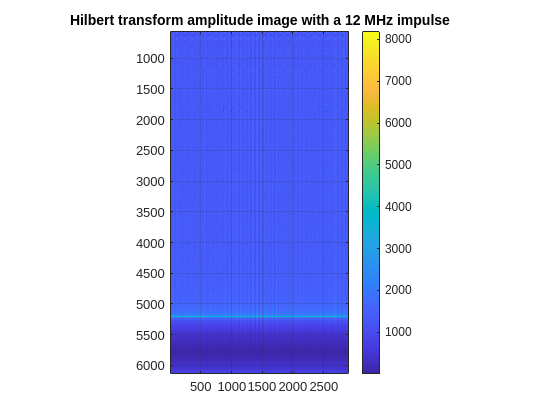

% Plotting read images
figure;
imagesc(abs(hilbert(rf2)));
title("Hilbert transform amplitude image with a 12 MHz impulse");
colorbar;
grid on;
axis image;

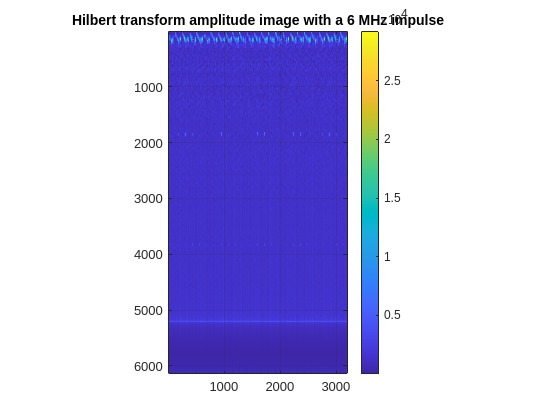

figure;
imagesc(abs(hilbert(rf3)));
title("Hilbert transform amplitude image with a 6 MHz impulse");
colorbar;
grid on;
axis image;

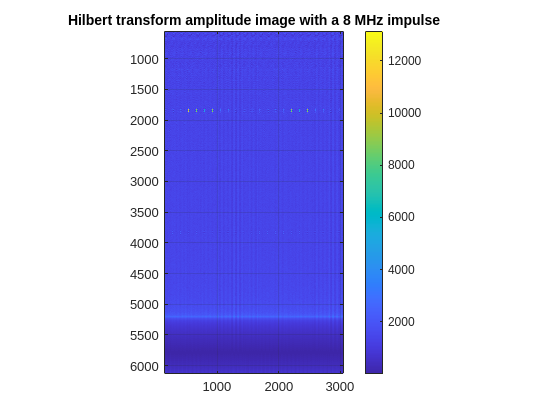

figure;
imagesc(abs(hilbert(rf4)));
title("Hilbert transform amplitude image with a 8 MHz impulse");
colorbar;
grid on;
axis image;

% Filtering first frames
framestart12MHz=80;
framestart6MHz=140;
framestart8MHz=120;
c0=1540;                                                                    % propagating S.O.S. in empty space. This is used just
                                                                            % visualize the image before computing real S.O.S. Assumed
                                                                            % to be similar to "Soft tissue" [m/s].
rfIMAGE2=rf2(:,framestart12MHz:framestart12MHz+Nlines);                     % visually select where first frame begins and isolate it
rfIMAGE2=rfIMAGE2./max(max(rfIMAGE2));                                      % image normalization (cathing the max in the matrix)

rfIMAGE3=rf3(:,framestart6MHz:framestart6MHz+Nlines);
rfIMAGE3=rfIMAGE3./max(max(rfIMAGE3));    

rfIMAGE4=rf4(:,framestart8MHz:framestart8MHz+Nlines);
rfIMAGE4=rfIMAGE4./max(max(rfIMAGE4)); 

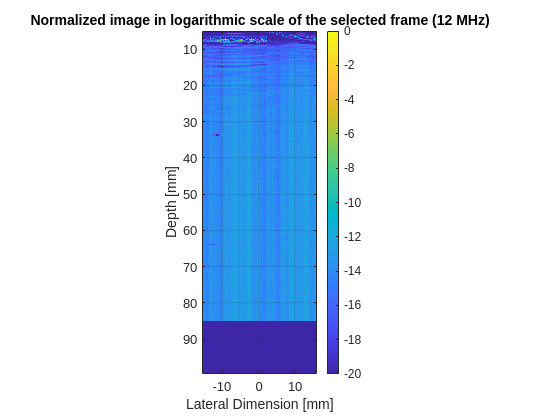

% Plot selected frames
figure;
imagesc(LateralDimension,Depth*1000,20*log10(abs(rfIMAGE2)));
clim([-20 0]);                                                              % clips colors to have prettier plots
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Normalized image in logarithmic scale of the selected frame (12 MHz)");
colorbar;
grid on;
axis image;  

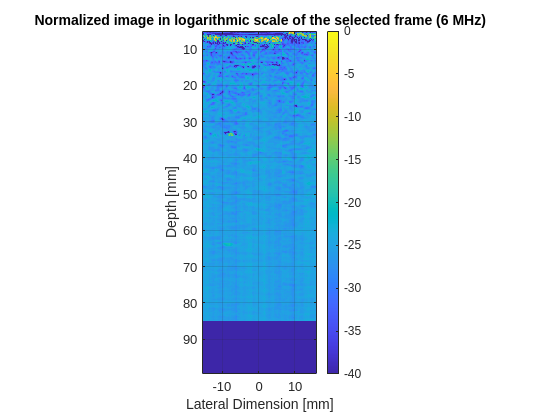

figure;
imagesc(LateralDimension,Depth*1000,20*log10(abs(rfIMAGE3)));
clim([-40 0]);                                                              % clips colors to have prettier plots
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Normalized image in logarithmic scale of the selected frame (6 MHz)");
colorbar;
grid on;
axis image;  

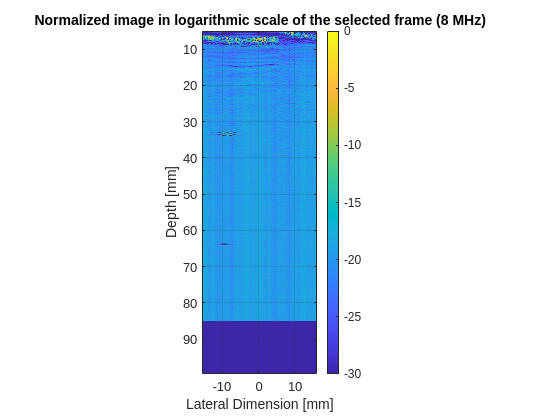

figure;
imagesc(LateralDimension,Depth*1000,20*log10(abs(rfIMAGE4)));
clim([-30 0]);                                                              % clips colors to have prettier plots
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Normalized image in logarithmic scale of the selected frame (8 MHz)");
colorbar;
grid on;
axis image;  

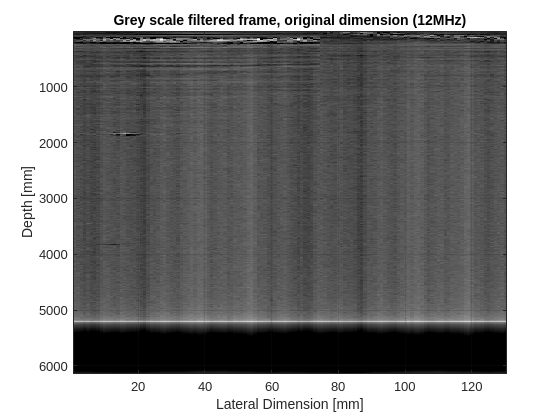

% Plot true dimensions selected frame
figure;
imagesc(20*log10(abs(abs(hilbert(rfIMAGE2)))));
clim([-20 0]);
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Grey scale filtered frame, original dimension (12MHz)");
grid on;
colormap('gray'); 

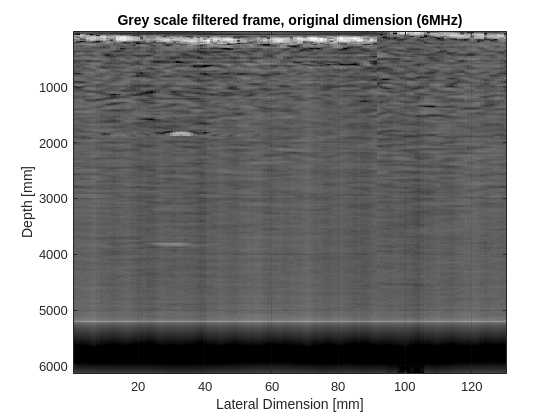

figure;
imagesc(20*log10(abs(abs(hilbert(rfIMAGE3)))));
clim([-40 0]);
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Grey scale filtered frame, original dimension (6MHz)");
grid on;
colormap('gray'); 

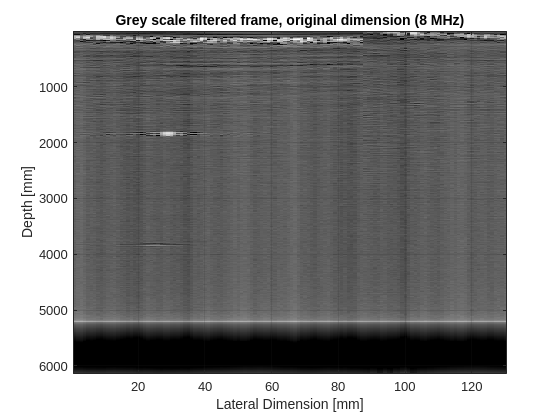

figure;
imagesc(20*log10(abs(abs(hilbert(rfIMAGE4)))));
clim([-30 0]);
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Grey scale filtered frame, original dimension (8 MHz)");
grid on;
colormap('gray'); 

### Speed of Sound computation

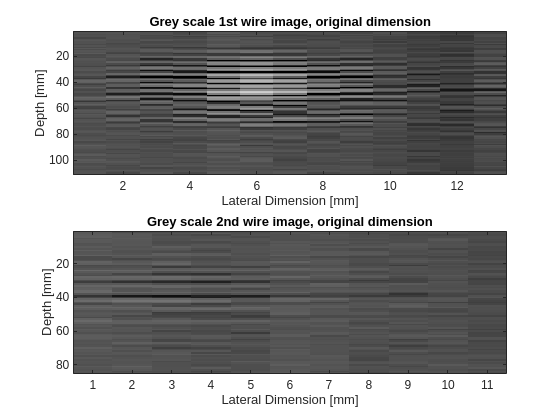

% Extract wires
ImageWire1_12MHz=abs(hilbert(rfIMAGE2(1800:1910,11:23)));                          % isolating one of the wires in the frame
                                                                                  % pay attention to consider the real dimension of the frame
ImageWire2_12MHz=abs(hilbert(rfIMAGE2(3790:3874,10:20)));   

figure;
subplot(2,2,[1 2]);
imagesc(20*log10(abs(ImageWire1_12MHz)));
clim([-20 0]);
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Grey scale 1st wire image, original dimension");
colormap('gray');     

subplot(2,2, [3 4]);
imagesc(20*log10(abs(ImageWire2_12MHz)));
clim([-20 0]);
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Grey scale 2nd wire image, original dimension");
colormap('gray');  

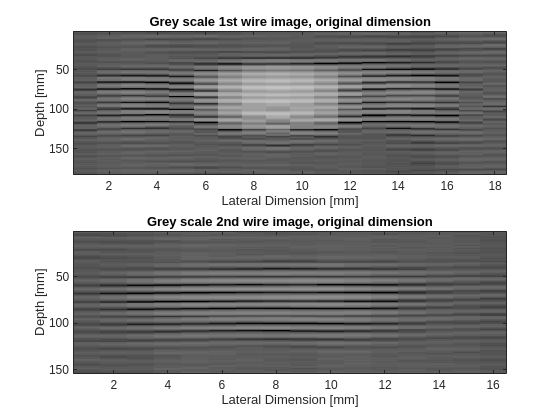

ImageWire1_6MHz=abs(hilbert(rfIMAGE3(1756:1938,25:42)));                          % isolating one of the wires in the frame
                                                                                  % pay attention to consider the real dimension of the frame
ImageWire2_6MHz=abs(hilbert(rfIMAGE3(3751:3904,23:38)));   

figure;
subplot(2,2,[1 2]);
imagesc(20*log10(abs(ImageWire1_6MHz)));
clim([-40 0]);
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Grey scale 1st wire image, original dimension");
colormap('gray');     

subplot(2,2, [3 4]);
imagesc(20*log10(abs(ImageWire2_6MHz)));
clim([-40 0]);
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Grey scale 2nd wire image, original dimension");
colormap('gray');  

ImageWire1_8MHz=abs(hilbert(rfIMAGE4(1786:1911,22:35)));                          % isolating one of the wires in the frame
                                                                                  % pay attention to consider the real dimension of the frame
ImageWire2_8MHz=abs(hilbert(rfIMAGE4(3777:3865,20:30)));   

figure;
subplot(2,2,[1 2]);
imagesc(20*log10(abs(ImageWire1_6MHz)));
clim([-40 0]);
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Grey scale 1st wire image, original dimension");
colormap('gray');     

subplot(2,2, [3 4]);
imagesc(20*log10(abs(ImageWire2_6MHz)));
clim([-40 0]);
xlabel('Lateral Dimension [mm]');
ylabel('Depth [mm]');
title("Grey scale 2nd wire image, original dimension");
colormap('gray');  

[depth1_12MHz,latdim1_12MHz]=find(ImageWire1_12MHz==max(max(ImageWire1_12MHz)));                     % returns the matrix indices of the maximum point
[depth2_12MHz,latdim2_12MHz]=find(ImageWire2_12MHz==max(max(ImageWire2_12MHz)));

[depth1_6MHz,latdim1_6MHz]=find(ImageWire1_6MHz==max(max(ImageWire1_6MHz)));                         % returns the matrix indices of the maximum point
[depth2_6MHz,latdim2_6MHz]=find(ImageWire2_6MHz==max(max(ImageWire2_6MHz)));

[depth1_8MHz,latdim1_8MHz]=find(ImageWire1_8MHz==max(max(ImageWire1_8MHz)));                         % returns the matrix indices of the maximum point
[depth2_8MHz,latdim2_8MHz]=find(ImageWire2_8MHz==max(max(ImageWire2_8MHz)));

### Final step

offset1wire_12MHz = 1800;                                                          % starting of first wire image
offset2wire_12MHz = 3790;                                                          % starting of second wire image

offset1wire_6MHz = 1756;                                                           % starting of first wire image
offset2wire_6MHz = 3751;                                                           % starting of second wire image

offset1wire_8MHz = 1786;                                                           % starting of first wire image
offset2wire_8MHz = 3777;                                                           % starting of second wire image
                                                          
time1to2_12MHz = (abs((offset1wire_12MHz+depth1_12MHz)-(offset2wire_12MHz+depth2_12MHz))/fs);               % time to travel one-way "space" [s]
SOS_12MHz = (2*space/time1to2_12MHz);                                                                       % speed of sound taking into consideration that
                                                                                                            % the wave needs to go back and forth. 
time1to2_6MHz = (abs((offset1wire_6MHz+depth1_6MHz)-(offset2wire_6MHz+depth2_6MHz))/fs);
SOS_6MHz = (2*space/time1to2_6MHz);              
                                                                                                            
time1to2_8MHz = (abs((offset1wire_8MHz+depth1_8MHz)-(offset2wire_8MHz+depth2_8MHz))/fs);               
SOS_8MHz = (2*space/time1to2_8MHz);                                                                       
                                                                                                            
SOSarray = [SOS, SOS_12MHz, SOS_6MHz, SOS_8MHz];
avgSOS = mean(SOSarray);
varSOS = var(SOSarray);

display = ['Average S.O.S. : ', num2str(avgSOS), '[m/s]  Variance S.O.S : ', num2str(varSOS), ' [m/s]'];                                                                
disp(display)

Average S.O.S. : 1514.0162[m/s]  Variance S.O.S : 23.6963 [m/s]
